# Extract a thermodynamically consistent subnetwork from a given model

## **Author(s): Ronan M.T. Fleming, School of Medicine, University of Galway**

## **Reviewer(s): **

- Identify the largest subset of a model that admits a thermodynamically consistent flux

- Specify a random subset of active/inactive reactions and present/absent metabolites

- Compute the smallest thermodynamically consistent subnetwork containing a list of present metabolites and active reactions, and not containing a list of absent metabolites and inactive reactions

[solverOK,solverInstalled]=changeCobraSolver('ibm_cplex','all');


 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > ibm_cplex (version 1210) is compatible and fully tested with MATLAB R2021a on your operating system.
 > changeCobraSolver: Solver for LP problems has been set to ibm_cplex.

 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > ibm_cplex (version 1210) is compatible and fully tested with MATLAB R2021a on your operating system.
 > changeCobraSolver: Solver for MILP problems has been set to ibm_cplex.

 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > ibm_cplex (version 1210) is compatible and fully tested with MATLAB R2021a on your operating system.
 > changeCobraSolver: Solver for QP problems has been set to ibm_cplex.

 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > ibm_cplex (version 1210) is compatible and fully tested with MATLAB R2021a on your operating system.
 > changeCobraSolver: Solver for MIQP problems has been set to ibm_cplex.
 > changeCob

%[solverOK,solverInstalled]=changeCobraSolver('gurobi','all');
%[solverOK,solverInstalled]=changeCobraSolver('ibm_cplex','QP');

## Load model

modelToLoad='circularToy';
modelToLoad='ecoli_core';
modelToLoad='modelRecon3MitoOpen';
modelToLoad='Recon3DModel';
%modelToLoad='iDopa';

Load a model

driver_thermoModelLoad

Model loaded: Recon3DModel
lower bounds greater than zero
Internal stochiometric nullspace computed in 4.5238 seconds.


## Stoichiometric consistency

if ~isfield(model,'SConsistentRxnBool')  || ~isfield(model,'SConsistentMetBool')
    massBalanceCheck=0;
    %massBalanceCheck=1;
    printLevel=2;
    [SConsistentMetBool, SConsistentRxnBool, SInConsistentMetBool, SInConsistentRxnBool, unknownSConsistencyMetBool, unknownSConsistencyRxnBool, model,stoichConsistModel]...
        = findStoichConsistentSubset(model, massBalanceCheck, printLevel);
else
    %Extract stoich consistent submodel
    if any(~model.SConsistentMetBool)
        rxnRemoveMethod='inclusive';%maintains stoichiometric consistency
        [stoichConsistModel, rxnRemoveList] = removeMetabolites(model, model.mets(~model.SConsistentMetBool),rxnRemoveMethod);
        SConsistentRxnBool2=~ismember(model.rxns,rxnRemoveList);
        if ~all(model.SConsistentRxnBool==SConsistentRxnBool2)
            error('inconsistent reaction removal')
        end
        try
            stoichConsistModel = removeUnusedGenes(stoichConsistModel);
        catch ME
            disp(ME.message)
        end
    else
        stoichConsistModel = model;
    end
end

[nMet,nRxn]=size(stoichConsistModel.S)

nMet = 5835

nRxn = 10600

## Flux consistency

fluxConsistentParam.method='fastcc';%can handle additional constraints
fluxConsistentParam.printLevel=1;
[~,~,~,~,stoichConsistModel]= findFluxConsistentSubset(stoichConsistModel,fluxConsistentParam);

Extract flux consistent submodel

if any(~stoichConsistModel.fluxConsistentRxnBool)
    rxnRemoveList = stoichConsistModel.rxns(~stoichConsistModel.fluxConsistentRxnBool);
    stoichFluxConsistModel = removeRxns(stoichConsistModel, rxnRemoveList,'metRemoveMethod','exclusive','ctrsRemoveMethod','inclusive');
    try
        stoichFluxConsistModel = removeUnusedGenes(stoichFluxConsistModel);
        catch ME
        disp(ME.message)
    end
else
    stoichFluxConsistModel = stoichConsistModel;
end
[nMet,nRxn]=size(stoichFluxConsistModel.S)

nMet = 5835

nRxn = 10600

## Thermodynamic consistency

%save('debug_prior_to_findThermoConsistentFluxSubset.mat')
%return
param.printLevel = 1;
param.relaxBounds=0;
param.acceptRepairedFlux=1;
[thermoFluxConsistentMetBool,thermoFluxConsistentRxnBool,stoichFluxConsistModel,stoichFluxThermoConsistModel] = findThermoConsistentFluxSubset(stoichFluxConsistModel,param);

--- findThermoFluxConsistentSubset START ----
                 printLevel: 1
                relaxBounds: 0
         acceptRepairedFlux: 1
                    epsilon: 1.0000e-06
                formulation: 'pqzw'
            iterationMethod: 'random'
                       nMax: 20
            warmStartMethod: 'random'
            thetaMultiplier: 1.5000
                      theta: 0.5000
            regularizeOuter: 0
    thermoConsistencyMethod: 'cycleFreeFlux'
                     bigNum: 10000
                      debug: 0

optCardThermo objective data:
         0.1 = beta, the global weight on one-norm of internal reaction rate.
          -5 = min(g0), the local weight on zero-norm of internal reaction rate.
          -0 = max(g0), the local weight on zero-norm of internal reaction rate.
           0 = min(h0), the local weight on zero-norm of metabolite production rate.
           0 = max(h0), the local weight on zero-norm of metabolite production rate.

optimizeCardinality o

ans = 9.1346e-07

ans = 0

ans = 0

solution = struct with fields:
    stat: 1
       v: [19391×1 double]
       r: [23417×1 double]
       p: [19391×1 double]
       q: [19391×1 double]


solutionRelaxed1 = struct with fields:
            full: [19391×1 double]
             obj: 26.3611
           rcost: [19391×1 double]
            dual: [23417×1 double]
           slack: [23417×1 double]
          solver: 'ibm_cplex'
       algorithm: 'Automatic'
            stat: 1
        origStat: 1
    origStatText: 'Optimal solution found'
            time: 1.2415
           basis: []


solutionRelaxed2 = struct with fields:
            full: [19391×1 double]
             obj: 0
           rcost: [19391×1 double]
            dual: [23417×1 double]
           slack: [23417×1 double]
          solver: 'ibm_cplex'
       algorithm: 'Automatic'
            stat: 1
        origStat: 1
    origStatText: 'Optimal solution found'
            time: 0.6092
           basis: []


solutionRelaxed3 = struct with fields:
            full: [19391×1 double]
             obj: 0
           rcost: [19391×1 double]
            dual: [23417×1 double]
           slack: [23417×1 double]
          solver: 'ibm_cplex'
       algorithm: 'Automatic'
            stat: 1
        origStat: 1
    origStatText: 'Optimal solution found'
            time: 0.3797
           basis: []


cycleFreeFlux: No solution found, try using a different solver.

cycleFreeFlux: No solution found.
Debugging relaxation etc...
            full: []
             obj: []
           rcost: []
            dual: []
           slack: []
          solver: 'ibm_cplex'
       algorithm: 'Automatic'
            stat: 0
        origStat: 3
    origStatText: 'Model has been proved infeasible'
            time: 0.0305
           basis: []

  itn         obj     obj_old    err(obj)      err(x)   card(v)   card(r)   card(p)   card(q)
    0      14.072       66355       66341      164.43      3913         0       543       541
    1        1391      14.072      1376.9      48.563      2734         0       692       717
    2      944.42        1391      446.54      62.844      3799         0       652       666
    3      1526.3      944.42      581.91      64.636      3026         0       712       702
    4      828.59      1526.3      697.73       63.09      3157         0       574       605
    

ans = 9.1346e-07

ans = 0

ans = 0

solution = struct with fields:
    stat: 1
       v: [19391×1 double]
       r: [23417×1 double]
       p: [19391×1 double]
       q: [19391×1 double]


solutionRelaxed1 = struct with fields:
            full: [19391×1 double]
             obj: 26.3611
           rcost: [19391×1 double]
            dual: [23417×1 double]
           slack: [23417×1 double]
          solver: 'ibm_cplex'
       algorithm: 'Automatic'
            stat: 1
        origStat: 1
    origStatText: 'Optimal solution found'
            time: 1.3163
           basis: []


solutionRelaxed2 = struct with fields:
            full: [19391×1 double]
             obj: 0
           rcost: [19391×1 double]
            dual: [23417×1 double]
           slack: [23417×1 double]
          solver: 'ibm_cplex'
       algorithm: 'Automatic'
            stat: 1
        origStat: 1
    origStatText: 'Optimal solution found'
            time: 0.5761
           basis: []


solutionRelaxed3 = struct with fields:
            full: [19391×1 double]
             obj: 0
           rcost: [19391×1 double]
            dual: [23417×1 double]
           slack: [23417×1 double]
          solver: 'ibm_cplex'
       algorithm: 'Automatic'
            stat: 1
        origStat: 1
    origStatText: 'Optimal solution found'
            time: 0.3650
           basis: []


76.81% thermodynamically feasible internal fluxes (checked by v2QNty method).
                iter             card(y)                  nz       %feas int.nz.   tot %feas int.nz.   tot %feas ext.nz.           iteration         formulation
                   1                5303                7882                0.68                0.50                0.80              random                pqzw
                   2                2376                3075                1.00                0.69                0.93              random                pqzw
                   3                1427                1708                1.00                0.77                0.98              random                pqzw
                   4                1022                1296                1.00                0.83                0.99              random                pqzw
                   5                 769                 794                1.00                0.86                1

Size of the largest flux, stoich and thermo consistent submodel

[nMet,nRxn]=size(stoichFluxThermoConsistModel.S)
save(['~/work/sbgCloud/programModelling/projects/thermoModel/results/thermoKernel/' modelToLoad '_stoichFluxThermoConsistModel.mat'],'stoichFluxThermoConsistModel')

%modelToLoad='Recon3DModel';
load(['~/work/sbgCloud/programModelling/projects/thermoModel/results/thermoKernel/' modelToLoad '_stoichFluxThermoConsistModel.mat'],'stoichFluxThermoConsistModel')

## Nullspace

Nullspace is necessary for backup check of thermodynamic consistency using thermoFlux2QNty 

[stoichFluxThermoConsistModel,rankK,nnzK,timeTaken] = internalNullspace(stoichFluxThermoConsistModel);
rankK

rankK = 5485

## Data to define a thermodynamically consistent subnetwork

Setup random data to select a random subset

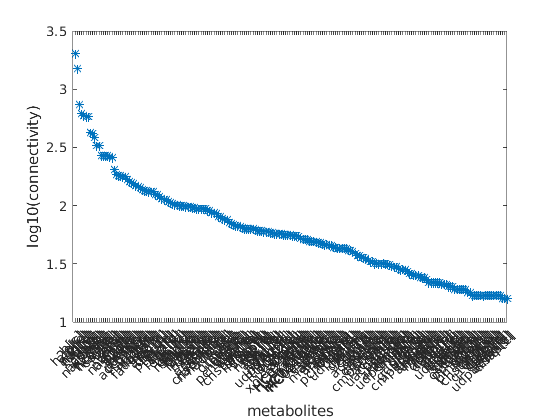

param.n=200;
[rankMetConnectivity,rankMetInd,rankConnectivity] = rankMetabolicConnectivity(stoichFluxThermoConsistModel,param);

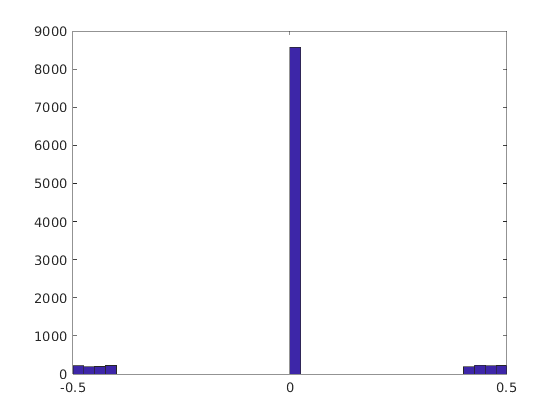

[nMet,nRxn]=size(stoichFluxThermoConsistModel.S);
rxnWeights=rand(nRxn,1)-0.5;
rxnWeights(~stoichFluxThermoConsistModel.SConsistentRxnBool)=0;

coreRxnBool=rxnWeights<-0.45;
removeRxnBool=rxnWeights>0.45;
if 0
    rxnWeights(rxnWeights>0.4)=1;
    rxnWeights(rxnWeights<-0.4)=-1;
end
rxnWeights(rxnWeights>=-0.4 & rxnWeights<=0.4)=0;
hist(rxnWeights,40)

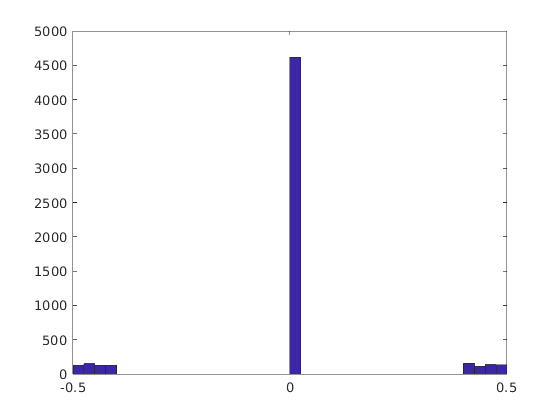

metWeights=rand(nMet,1)-0.5;
metWeights(rankMetInd(1:200))=0;
coreMetBool=metWeights<-0.45;
removeMetBool=metWeights>0.45;
if 0
    metWeights(metWeights>0.4)=1;
    metWeights(metWeights<-0.4)=-1;
end
metWeights(metWeights>=-0.4 & metWeights<=0.4)=0;
hist(metWeights,40)

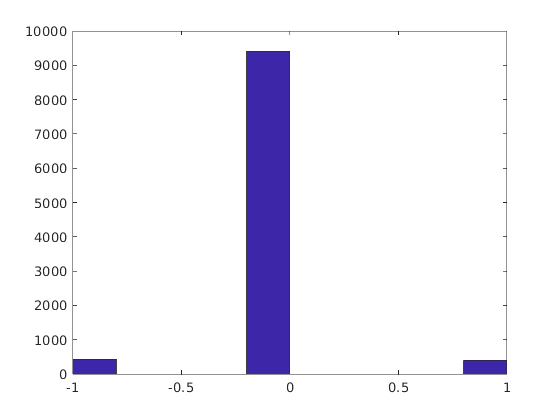

nlt=length(coreRxnBool);
activeInactiveRxn=zeros(nlt,1);
activeInactiveRxn(coreRxnBool)=1;
activeInactiveRxn(removeRxnBool)=-1;
hist(activeInactiveRxn)

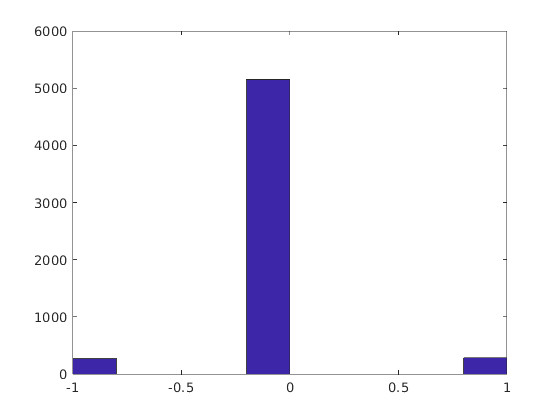

mlt=length(coreMetBool);
presentAbsentMet=zeros(mlt,1);
presentAbsentMet(coreMetBool)=1;
presentAbsentMet(removeMetBool)=-1;
if 0
    activeInactiveRxn(:)=0;
    presentAbsentMet(:)=0;
end
param.normalizeZeroNormWeights=0;

hist(presentAbsentMet)

## Compute the smallest thermodynamically consistent subnetwork given a list of present/absent metabolites and active/inactive reactions

--- thermoKernel START ----
thermoKernel parameters:
                  printLevel: 1
                 relaxBounds: 0
          acceptRepairedFlux: 1
                           n: 200
    normalizeZeroNormWeights: 0
                 formulation: 'pqzwrs'
                     epsilon: 1.0000e-06
           removeOrphanGenes: 1
              nbMaxIteration: 30
                        nMax: 20
             iterationMethod: 'greedyRandom'

            warmStartMethod: 'random'
                formulation: 'pqzwrs'
            thetaMultiplier: 1.5000
                      theta: 0.5000
            regularizeOuter: 1
                    epsilon: 1.0000e-06
                 printLevel: 1
                relaxBounds: 0
         acceptRepairedFlux: 1
    thermoConsistencyMethod: 'cycleFreeFlux'
                     bigNum: 10000
                      debug: 0

optCardThermo objective data:
           1 = beta, the global weight on one-norm of internal reaction rate.
        -0.5 = min(g0), the l

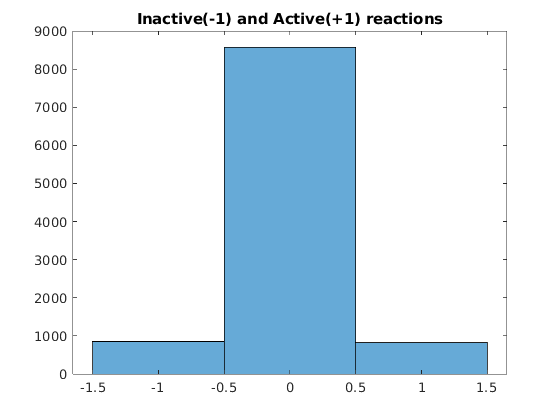

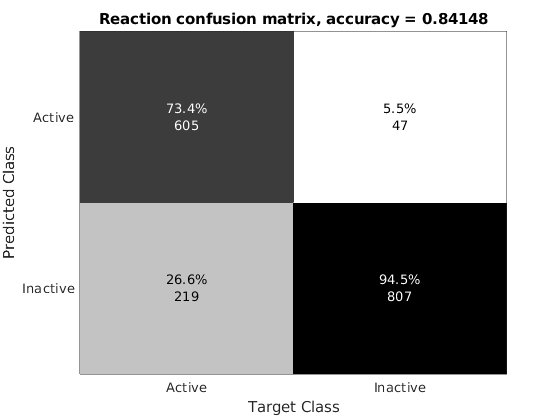

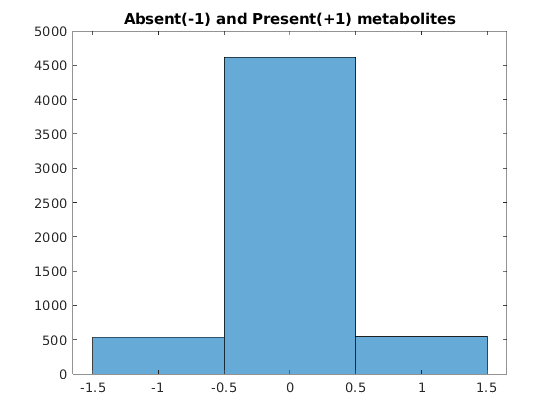

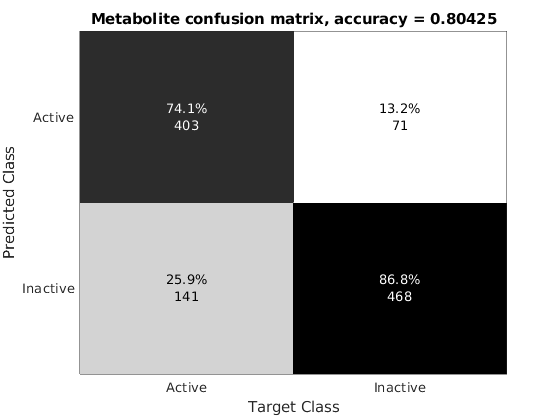

--- thermoKernel END ----


[tissueModel, thermoModelMetBool, thermoModelRxnBool] = thermoKernel(stoichFluxThermoConsistModel, activeInactiveRxn, rxnWeights, presentAbsentMet, metWeights,param);

[nMet,nRxn]=size(tissueModel.S)

nMet = 2203

nRxn = 2986

Compare the target versus predicted model

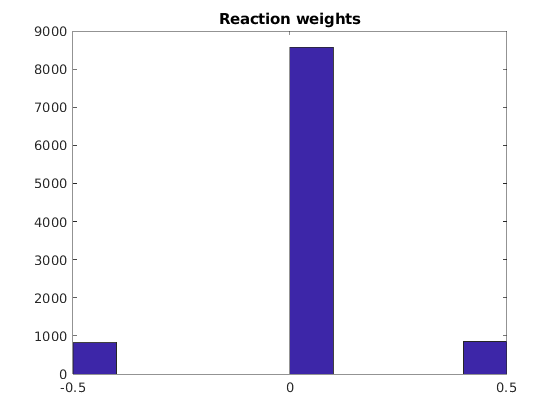

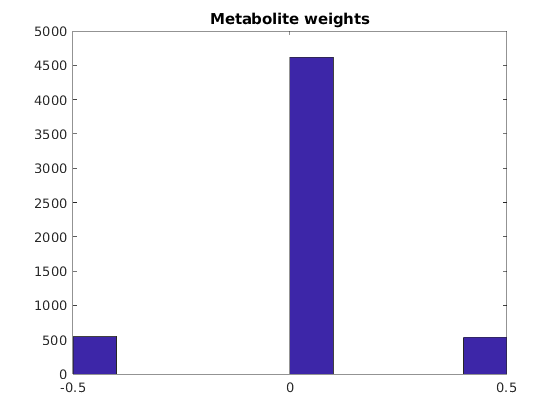

%plotThermoCoreStats(activeInactiveRxn, presentAbsentMet, thermoModelMetBool, thermoModelRxnBool);
plotThermoKernelExtractStats(stoichFluxThermoConsistModel, activeInactiveRxn, rxnWeights, presentAbsentMet, metWeights, thermoModelMetBool, thermoModelRxnBool)

#### Save weights

rxnWeightsTmp=rxnWeights;
metWeightsTmp=metWeights;

## Submodel with just metabolites specified

--- thermoKernel START ----
thermoKernel parameters:
                  printLevel: 1
                 relaxBounds: 0
          acceptRepairedFlux: 1
                           n: 200
    normalizeZeroNormWeights: 0
                 formulation: 'pqzwrs'
                     epsilon: 1.0000e-06
           removeOrphanGenes: 1
              nbMaxIteration: 30
                        nMax: 20
             iterationMethod: 'greedyRandom'

            warmStartMethod: 'random'
                formulation: 'pqzwrs'
            thetaMultiplier: 1.5000
                      theta: 0.5000
            regularizeOuter: 1
                    epsilon: 1.0000e-06
                 printLevel: 1
                relaxBounds: 0
         acceptRepairedFlux: 1
    thermoConsistencyMethod: 'cycleFreeFlux'
                     bigNum: 10000
                      debug: 0

optCardThermo objective data:
           1 = beta, the global weight on one-norm of internal reaction rate.
           0 = min(g0), the l

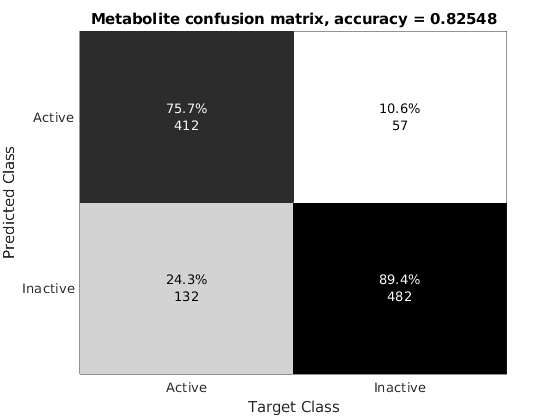

--- thermoKernel END ----


metWeights=metWeightsTmp;
rxnWeights(:)=0;
[tissueModel, thermoModelMetBool, thermoModelRxnBool] = thermoKernel(stoichFluxThermoConsistModel, activeInactiveRxn, rxnWeights, presentAbsentMet, metWeights,param);

[nMet,nRxn]=size(tissueModel.S)

nMet = 1870

nRxn = 2635

Compare the target versus predicted model

plotThermoKernelExtractStats(stoichFluxThermoConsistModel, activeInactiveRxn, rxnWeights, presentAbsentMet, metWeights, thermoModelMetBool, thermoModelRxnBool)

## Submodel with just reactions specified

--- thermoKernel START ----
thermoKernel parameters:
                  printLevel: 1
                 relaxBounds: 0
          acceptRepairedFlux: 1
                           n: 200
    normalizeZeroNormWeights: 0
                 formulation: 'pqzwrs'
                     epsilon: 1.0000e-06
           removeOrphanGenes: 1
              nbMaxIteration: 30
                        nMax: 20
             iterationMethod: 'greedyRandom'

            warmStartMethod: 'random'
                formulation: 'pqzwrs'
            thetaMultiplier: 1.5000
                      theta: 0.5000
            regularizeOuter: 1
                    epsilon: 1.0000e-06
                 printLevel: 1
                relaxBounds: 0
         acceptRepairedFlux: 1
    thermoConsistencyMethod: 'cycleFreeFlux'
                     bigNum: 10000
                      debug: 0

optCardThermo objective data:
           1 = beta, the global weight on one-norm of internal reaction rate.
        -0.5 = min(g0), the l

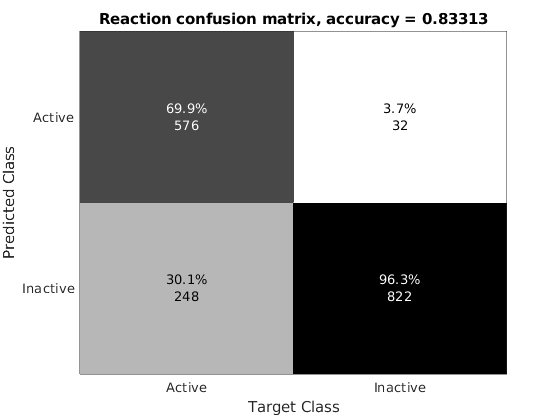

--- thermoKernel END ----


rxnWeights=rxnWeightsTmp;
metWeights(:)=0;
[tissueModel, thermoModelMetBool, thermoModelRxnBool] = thermoKernel(stoichFluxThermoConsistModel, activeInactiveRxn, rxnWeights, presentAbsentMet, metWeights,param);


[nMet,nRxn]=size(tissueModel.S)

nMet = 1441

nRxn = 1924

Compare the target versus predicted model

plotThermoKernelExtractStats(stoichFluxThermoConsistModel, activeInactiveRxn, rxnWeights, presentAbsentMet, metWeights, thermoModelMetBool, thermoModelRxnBool)

## Submodel with just active metabolites specified

metWeightsRed=metWeightsTmp;
rxnWeightsRed=rxnWeightsTmp*0;
metWeightsRed(metWeightsRed>=0)=0;

--- thermoKernel START ----
thermoKernel parameters:
                  printLevel: 1
                 relaxBounds: 0
          acceptRepairedFlux: 1
                           n: 200
    normalizeZeroNormWeights: 0
                 formulation: 'pqzwrs'
                     epsilon: 1.0000e-06
           removeOrphanGenes: 1
              nbMaxIteration: 30
                        nMax: 20
             iterationMethod: 'greedyRandom'

            warmStartMethod: 'random'
                formulation: 'pqzwrs'
            thetaMultiplier: 1.5000
                      theta: 0.5000
            regularizeOuter: 1
                    epsilon: 1.0000e-06
                 printLevel: 1
                relaxBounds: 0
         acceptRepairedFlux: 1
    thermoConsistencyMethod: 'cycleFreeFlux'
                     bigNum: 10000
                      debug: 0

optCardThermo objective data:
           1 = beta, the global weight on one-norm of internal reaction rate.
           0 = min(g0), the l

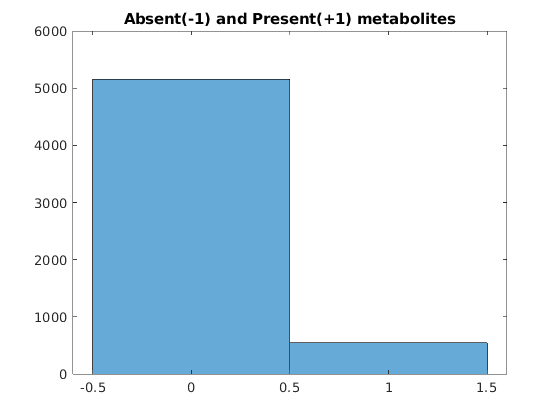

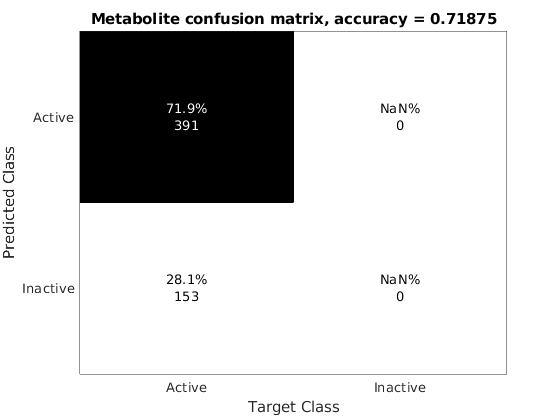

--- thermoKernel END ----


[tissueModel, thermoModelMetBool, thermoModelRxnBool] = thermoKernel(stoichFluxThermoConsistModel, activeInactiveRxn, rxnWeightsRed, presentAbsentMet, metWeightsRed,param);

[nMet,nRxn]=size(tissueModel.S)

nMet = 1448

nRxn = 1753

Compare the target versus predicted model

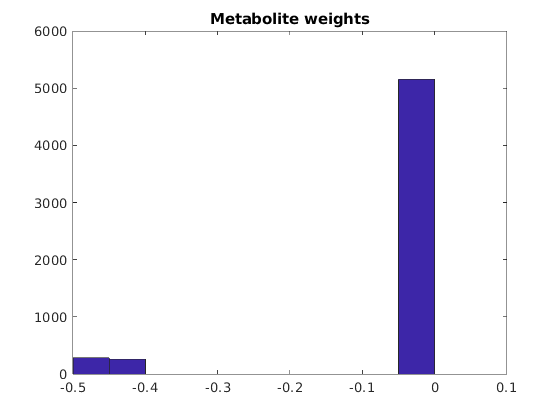

plotThermoKernelExtractStats(stoichFluxThermoConsistModel, activeInactiveRxn, rxnWeightsRed, presentAbsentMet, metWeightsRed, thermoModelMetBool, thermoModelRxnBool)

## Submodel with just active reactions specified

--- thermoKernel START ----
thermoKernel parameters:
                  printLevel: 1
                 relaxBounds: 0
          acceptRepairedFlux: 1
                           n: 200
    normalizeZeroNormWeights: 0
                 formulation: 'pqzwrs'
                     epsilon: 1.0000e-06
           removeOrphanGenes: 1
              nbMaxIteration: 30
                        nMax: 20
             iterationMethod: 'greedyRandom'

            warmStartMethod: 'random'
                formulation: 'pqzwrs'
            thetaMultiplier: 1.5000
                      theta: 0.5000
            regularizeOuter: 1
                    epsilon: 1.0000e-06
                 printLevel: 1
                relaxBounds: 0
         acceptRepairedFlux: 1
    thermoConsistencyMethod: 'cycleFreeFlux'
                     bigNum: 10000
                      debug: 0

optCardThermo objective data:
           1 = beta, the global weight on one-norm of internal reaction rate.
        -0.5 = min(g0), the l

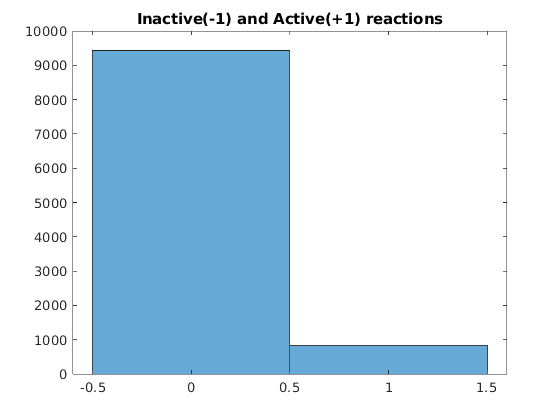

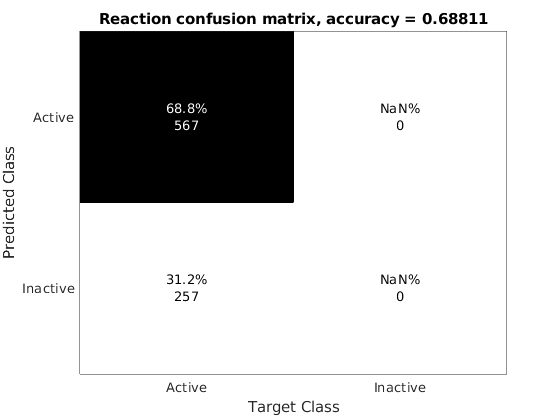

--- thermoKernel END ----


rxnWeightsRed=rxnWeightsTmp;
metWeightsRed=metWeightsTmp*0;
rxnWeightsRed(rxnWeightsRed>=0)=0;
[tissueModel, thermoModelMetBool, thermoModelRxnBool] = thermoKernel(stoichFluxThermoConsistModel, activeInactiveRxn, rxnWeightsRed, presentAbsentMet, metWeightsRed,param);


[nMet,nRxn]=size(tissueModel.S)

nMet = 1449

nRxn = 1915

Compare the target versus predicted model

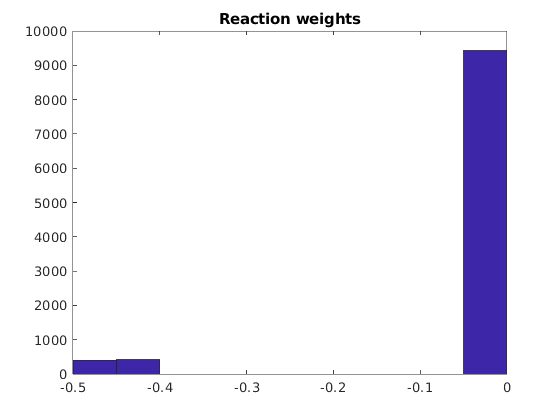

plotThermoKernelExtractStats(stoichFluxThermoConsistModel, activeInactiveRxn, rxnWeightsRed, presentAbsentMet, metWeightsRed, thermoModelMetBool, thermoModelRxnBool)

## *Acknowledgments*

Co-funded by the European Union's Horizon Europe Framework Programme (101080997)

## REFERENCES

[1] Ronan M T Fleming, Hulda S Haraldsdottir, Le Hoai Minh, Phan Tu Vuong, Thomas Hankemeier, Ines Thiele, Cardinality optimization in constraint-based modelling: application to human metabolism, *Bioinformatics*, Volume 39, Issue 9, September 2023, btad450, [https://doi.org/10.1093/bioinformatics/btad450](https://doi.org/10.1093/bioinformatics/btad450)

[2] Preciat, G., Wegrzyn, A. B., Luo, X., Thiele, I., Hankemeier, T., & Fleming, R. M. T. (2025). XomicsToModel: omics data integration and generation of thermodynamically consistent metabolic models. Nature Protocols. [https://doi.org/10.1038/s41596-025-01288-9](https://doi.org/10.1038/s41596-025-01288-9) 